## Initialize Variables

t_start = 0;    % Start Time
t_end = 5;      % End Time
dt = [1; 1/2; 1/4; 1/8]; % Time Steps To Investigate
dt_label = ["dt: 1.0", "dt: 0.5", "dt: 0.25", "dt: 0.125"]; % For Legend
p_init = 1;     % Initial Condition

C = ["g", "r", "b", "k"];   % Colors for Plot
LS = ["-", "-", "-", "-"];  %Line Styles for Plot
N = 41;                     % Number of Points for Plotting
t_plot = linspace(t_start,t_end,N); % Discrete Time-Intervals

%Calculate Exact solution for plotting
y_exact = zeros(size(t_plot));
for i = 1:length(t_plot)
    y_exact(i) = exact_soln(t_plot(i)); % Population Size at Time t(i)
end

### Plot Analytical Solution

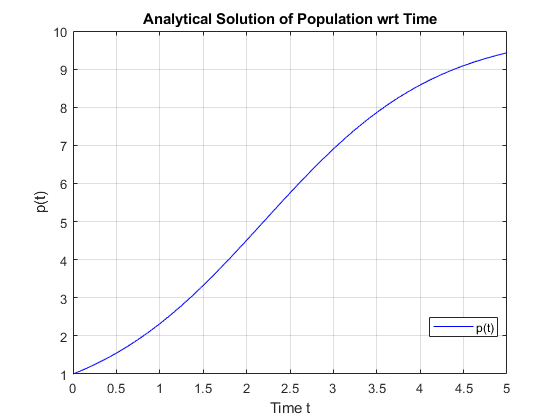

plot(t_plot,y_exact,"b-")
xlabel("Time t")
ylabel("p(t)")
title("Analytical Solution of Population wrt Time")
legend("p(t)", "Location","best")
grid on

### Runge-Kutta Method

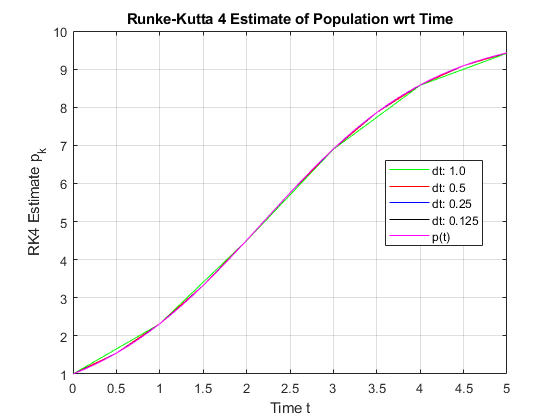

error_est = zeros(size(dt));
p_exact = zeros(size(dt));
half_error = zeros(size(error_est));
red_fact = zeros(size(error_est));
error2_k = zeros(size(dt));

%Run for all time-step sizes
for i = 1:length(dt)
    
    % Calculate RK4 Estimate
    [t_k, p_k] = runge(@ode, t_start, t_end, p_init, dt(i));
    
    % Calculate RK4 Estimate if dt = dt * 0.5
    [t_r, p_r] = runge(@ode, t_start, t_end, p_init, dt(i)*0.5);
    
    % Calculate Estimate Errors
    error_est(i) = approx_err(@exact_soln, t_k, p_k, dt(i));
    half_error(i) = approx_err(@exact_soln, t_r, p_r, dt(i)*0.5);
    
    %Calculate error reduction factor for half-time-step soln
    red_fact(i) = error_est(i) / half_error(i);

    %% PLOTTING
    if i > 1;  hold on; end
    
    % Create Plot
    plots(i) = plot(t_k,p_k,"Color",C(i), "LineStyle",LS(i));
    legend_str{i} = dt_label(i);
    
    if i == length(dt)
        % Add Analytical Solution as Reference at the last iteration
        plots(5) = plot(t_plot,y_exact,"m-");
        legend_str{5} = "p(t)";
        
        xlabel("Time t")
        ylabel("RK4 Estimate p_k")
        title("Runke-Kutta 4 Estimate of Population wrt Time")
        legend(plots, legend_str, "Location","best")
        grid on
        hold off
    end
end

### Table Summary for Runge-Kutta Method

T = custom_table(dt, error_est, red_fact,error2_k)

T = 4×4 table
    Time_Step      Error       Red_factor    Error2
    _________    __________    __________    ______

          1       0.0078944      15.109        0   
        0.5      0.00052249      15.121        0   
       0.25      3.4554e-05      15.473        0   
      0.125      2.2331e-06      15.717        0   


### Euler Method

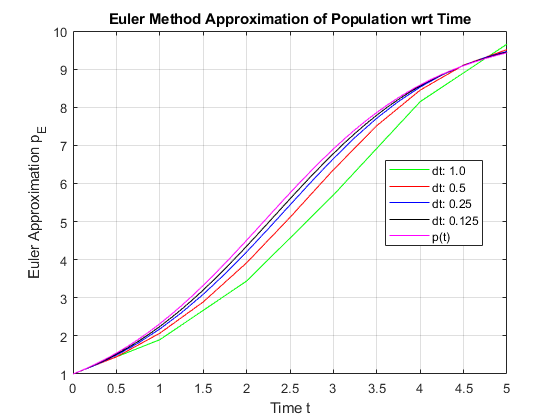

error_est_E = zeros(size(dt));
p_exact = zeros(size(dt));
half_error_E = zeros(size(error_est_E));
red_fact_E = zeros(size(error_est_E));
error2_E = zeros(size(dt));

%Run for all time-step sizes
for i = 1:length(dt)
    
    % Calculate Euler Approximation
    [t_E, p_E] = euler(@ode, t_end, p_init, dt(i));   
 
    % Calculate Euler Approximation if dt = dt * 0.5
    [t_Er, p_Er] = euler(@ode, t_end, p_init, dt(i)*0.5);    
    
    % Calculate Estimate Error
    error_est_E(i) = approx_err(@exact_soln, t_E, p_E, dt(i));
    
    % Calculate error for half time step and reduction factor
    half_error_E(i) = approx_err(@exact_soln, t_Er, p_Er, dt(i)*0.5);
    red_fact_E(i) = error_est_E(i) / half_error_E(i);
    
    %Calculate error against range kutta
    [t_k, p_k] = runge(@ode, t_start, t_end, p_init, dt(i));
    error2_E(i) = approx_err(@exact_soln, t_E, p_E, dt(i), p_k);

    %% PLOTTING
    if i > 1; hold on; end
    
    % Create Plot
    plots(i) = plot(t_E,p_E,"Color",C(i), "LineStyle",LS(i));
    legend_str{i} = dt_label(i);
    
    if i == length(dt)
        % Add Analytical Solution as Reference
        plots(5) = plot(t_plot,y_exact,"m-");
        legend_str{5} = "p(t)";
        
        xlabel("Time t")
        ylabel("Euler Approximation p_E")
        title("Euler Method Approximation of Population wrt Time")
        legend(plots, legend_str, "Location","best")
        grid on
        hold off
    end
end

### Table Summary for Euler Approximation

T = custom_table(dt, error_est_E, red_fact_E,error2_E)

T = 4×4 table
    Time_Step     Error      Red_factor     Error2 
    _________    ________    __________    ________

          1       0.77832      2.0337       0.77284
        0.5       0.38272      2.0159       0.38229
       0.25       0.18984      2.0087       0.18982
      0.125      0.094511      2.0046      0.094509


### Heun Method

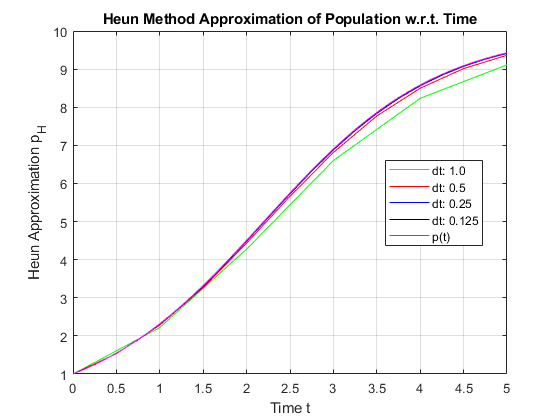

error_est_h = zeros(size(dt));
p_exact = zeros(size(dt));
half_error_h = zeros(size(dt));
red_fact_h = zeros(size(dt));
error2_h = zeros(size(dt));

%Run for all time-step sizes
for i = 1:length(dt)
    
    % Calculate Heun Approximation and error against exact soln
    [t_h, p_h] = heun(@ode, t_start, t_end, p_init, dt(i));
    error_est_h(i) = approx_err(@exact_soln, t_h, p_h, dt(i));
    
    % Calculate Heun Approximation if dt(i)*0.5 and err against exact soln
    [t_h2, p_h2] = heun(@ode, t_start, t_end, p_init, dt(i)*0.5);
    half_error_h(i) = approx_err(@exact_soln, t_h2, p_h2, dt(i)*0.5);
    
    % Calculate Error reduction factor for half time step
    red_fact_h(i) = error_est_h(i) / half_error_h(i);
    
    %Calculate error against range kutta
    [t_k, p_k] = runge(@ode, t_start, t_end, p_init, dt(i));
    error2_h(i) = approx_err(@exact_soln, t_h, p_h, dt(i), p_k);

    %% PLOTTING
    if i > 1; hold on; end
    
    % Create Plot
    plots(i) = plot(t_h,p_h,"Color",C(i), "LineStyle",LS(i));
    legend_str{i} = dt_label(i);
    
    if i == length(dt)
        % Add Analytical Solution as Reference at the last iteration
        plots(5) = plot(t_plot,y_exact,"m-");
        legend_str{5} = "p(t)";
        
        xlabel("Time t")
        ylabel("Heun Approximation p_H")
        title("Heun Method Approximation of Population w.r.t. Time")
        legend(plots, legend_str, "Location","best")
        grid on
        hold off
    end
end

### Table Summary for Heun Approximation

T = custom_table(dt, error_est_h, red_fact_h,error2_h)

T = 4×4 table
    Time_Step     Error      Red_factor     Error2  
    _________    ________    __________    _________

          1       0.27486      3.8328        0.26702
        0.5      0.071713      3.7975       0.071193
       0.25      0.018884      3.8681        0.01885
      0.125      0.004882      3.9261      0.0048798
